clear; clc; clear

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0]; grey = [0.5 0.5 0.5];


## HU ET AL. 2011/2012

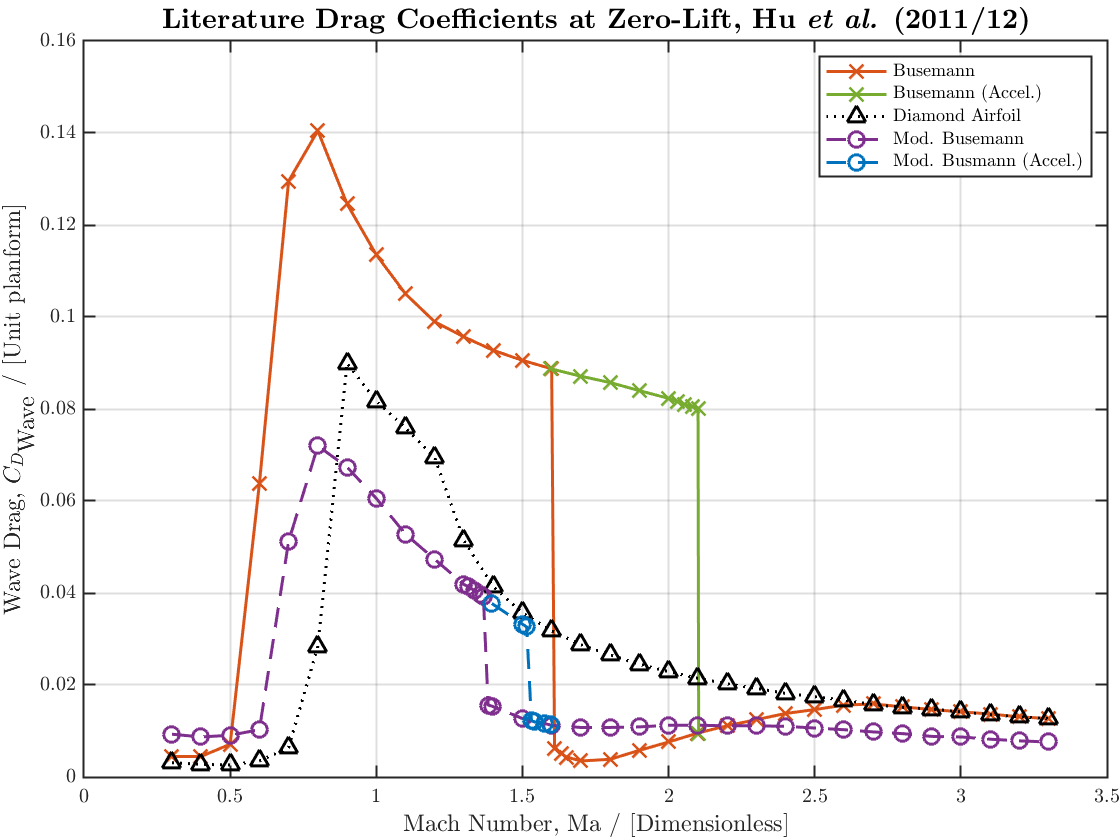


%FIG 16 - DRAG PLOT  - zero lift, Machs and Wave drags
%busemann
Hu_et_al_fig16_buseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.633744856,1.652263374,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_buseman_cd=[0.004453441,0.004453441,0.007125506,0.063724696,0.129554656,0.14048583,0.124574899,0.113522267,0.105020243,0.098947368,0.095668016,0.092753036,0.090566802,0.088744939,0.006153846,0.005060729,0.004331984,0.003481781,0.003846154,0.005789474,0.007611336,0.009554656,0.011133603,0.012469636,0.013805668,0.01465587,0.01562753,0.015870445,0.015263158,0.01465587,0.01417004,0.013684211,0.013076923,0.012712551];
%busemann accel
Hu_et_al_fig16_buseman_accel_machs=[1.596707819,1.697530864,1.802469136,1.899176955,2,2.030864198,2.053497942,2.082304527,2.100823045,2.102880658];
Hu_et_al_fig16_buseman_accel_cd=[0.088744939,0.087165992,0.085708502,0.084008097,0.082307692,0.081578947,0.08097166,0.08048583,0.080121457,0.009554656];
%diamond
Hu_et_al_fig16_diamond_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_diamond_cd=[0.003117409,0.002753036,0.002631579,0.003481781,0.006396761,0.028380567,0.089959514,0.081700405,0.075870445,0.069433198,0.051336032,0.041376518,0.035668016,0.031781377,0.028744939,0.026558704,0.024493927,0.02291498,0.02145749,0.020242915,0.019271255,0.018178138,0.017449393,0.016720648,0.015748988,0.0151417,0.014777328,0.01417004,0.013562753,0.013076923,0.012712551];
%modified accel
Hu_et_al_fig16_modifiedbuseman_accel_machs=[1.395061728,1.5,1.514403292,1.530864198,1.541152263,1.574074074,1.596707819];
Hu_et_al_fig16_modifiedbuseman_accel_cd=[0.037732794,0.033238866,0.032631579,0.012226721,0.011983806,0.011619433,0.011376518];
%modified
Hu_et_al_fig16_modifiedbuseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.314814815,1.335390947,1.355967078,1.366255144,1.382716049,1.397119342,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_modifiedbuseman_cd=[0.009311741,0.008704453,0.009068826,0.010283401,0.051214575,0.071983806,0.067368421,0.060566802,0.052793522,0.047327935,0.041862348,0.041376518,0.040526316,0.039676113,0.039311741,0.01562753,0.015384615,0.012712551,0.011255061,0.010769231,0.010769231,0.010890688,0.011255061,0.011255061,0.011133603,0.011133603,0.011012146,0.010647773,0.010283401,0.009797571,0.009433198,0.008825911,0.008704453,0.008218623,0.007854251,0.007611336];

figure
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",width,'color',orange,'markerSize',msize)
hold on
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",width,'color',green,'markerSize',msize)
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",width,'color',black,'markerSize',msize)
hold on
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",width,'color',purple,'markerSize',msize)
hold on
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",width,'color',blue,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-Lift, Hu \textit{et al.} (2011/12)}",'FontSize',tsize)
legend("Busemann","Busemann (Accel.)","Diamond Airfoil",...
    "Mod. Busemann","Mod. Busmann (Accel.)", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Kusunose et al (2011)

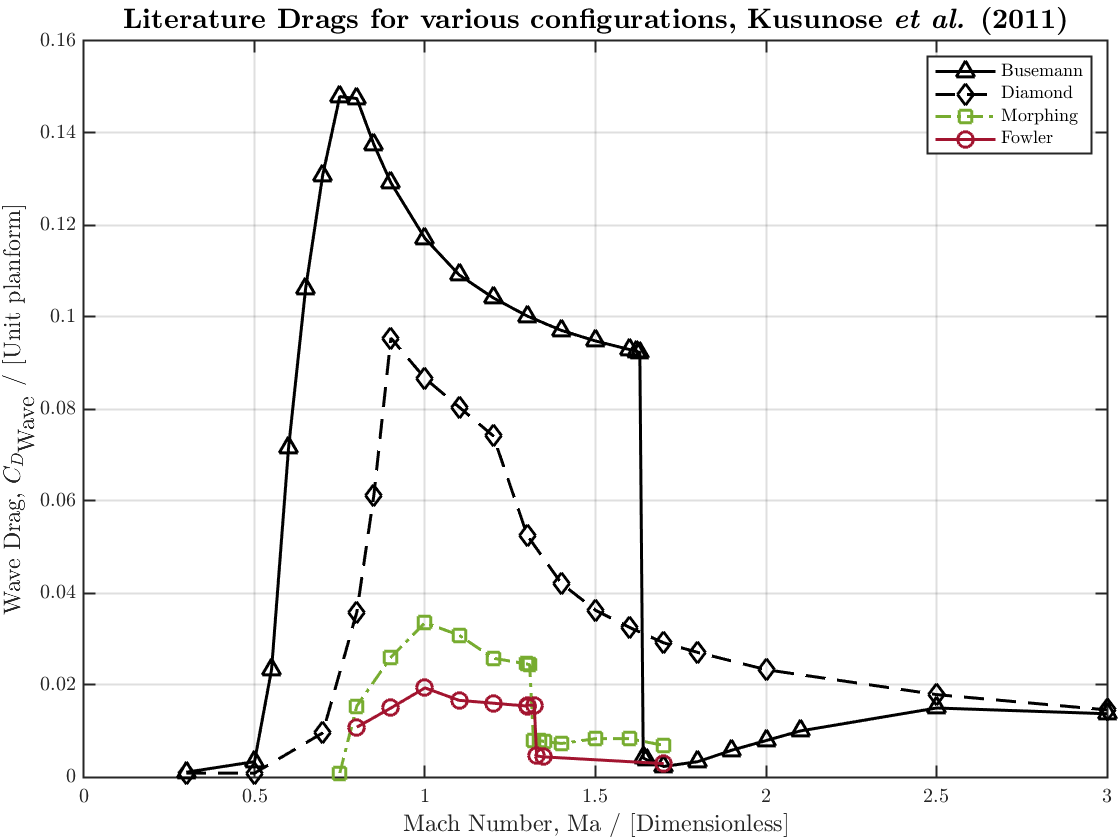

% KUSUNOSE  - Supersonic biplane—A review

%FIG 18 - cdwave across machs for 4 different airfoils
%busemann		diamond airfoil		morphing		fowler
Kusunose_review_fig18_buseman_machs=[0.3,0.5,0.55,0.6,0.65,0.7,0.75,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.62,1.63,1.64,1.65,1.7,1.8,1.9,2,2.1,2.5,3];
Kusunose_review_fig18_buseman_cd=[0.001041667,0.003333333,0.023333333,0.071666667,0.10625,0.130833333,0.147916667,0.1475,0.1375,0.129166667,0.117083333,0.109166667,0.104166667,0.100208333,0.097083333,0.094791667,0.092916667,0.0925,0.092291667,0.004166667,0.00375,0.002291667,0.003333333,0.005833333,0.007916667,0.01,0.015,0.01375];

Kusunose_review_fig18_diamond_machs=[0.3,0.5,0.7,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,2,2.5,3];
Kusunose_review_fig18_diamond_cd=[0.000833333,0.000833333,0.009583333,0.035833333,0.06125,0.095416667,0.086666667,0.080416667,0.074166667,0.0525,0.042083333,0.03625,0.0325,0.029166667,0.027083333,0.023333333,0.017916667,0.014583333];

Kusunose_review_fig18_morphing_machs=[0.75,0.8,0.9,1,1.1,1.2,1.297727273,1.306818182,1.318181818,1.336363636,1.35,1.4,1.5,1.6,1.7];
Kusunose_review_fig18_morphing_cd=[0.000833333,0.015416667,0.026041667,0.033541667,0.030833333,0.025833333,0.024583333,0.024375,0.007916667,0.007916667,0.007708333,0.007291667,0.008333333,0.008333333,0.006875];

Kusunose_review_fig18_fowler_machs=[0.8,0.9,1,1.1,1.2,1.3,1.3,1.320454545,1.327272727,1.347727273,1.7];
Kusunose_review_fig18_fowler_cd=[0.010833333,0.015,0.019375,0.016666667,0.016041667,0.015416667,0.015625,0.015625,0.004583333,0.004375,0.002916667];

figure
plot(Kusunose_review_fig18_buseman_machs,Kusunose_review_fig18_buseman_cd,'k^-',"LineWidth",width,'markerSize',msize)
hold on
plot(Kusunose_review_fig18_diamond_machs,Kusunose_review_fig18_diamond_cd,'kd--',"LineWidth",width,'markerSize',msize)
hold on
plot(Kusunose_review_fig18_morphing_machs,Kusunose_review_fig18_morphing_cd,'s-.',"LineWidth",width,'color',green,'markerSize',msize)
hold on
plot(Kusunose_review_fig18_fowler_machs,Kusunose_review_fig18_fowler_cd,'o-',"LineWidth",width,'color',red,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drags for various configurations, Kusunose \textit{et al.} (2011)}",'FontSize',tsize)
legend("Busemann","Diamond","Morphing","Fowler", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Drag Comparison

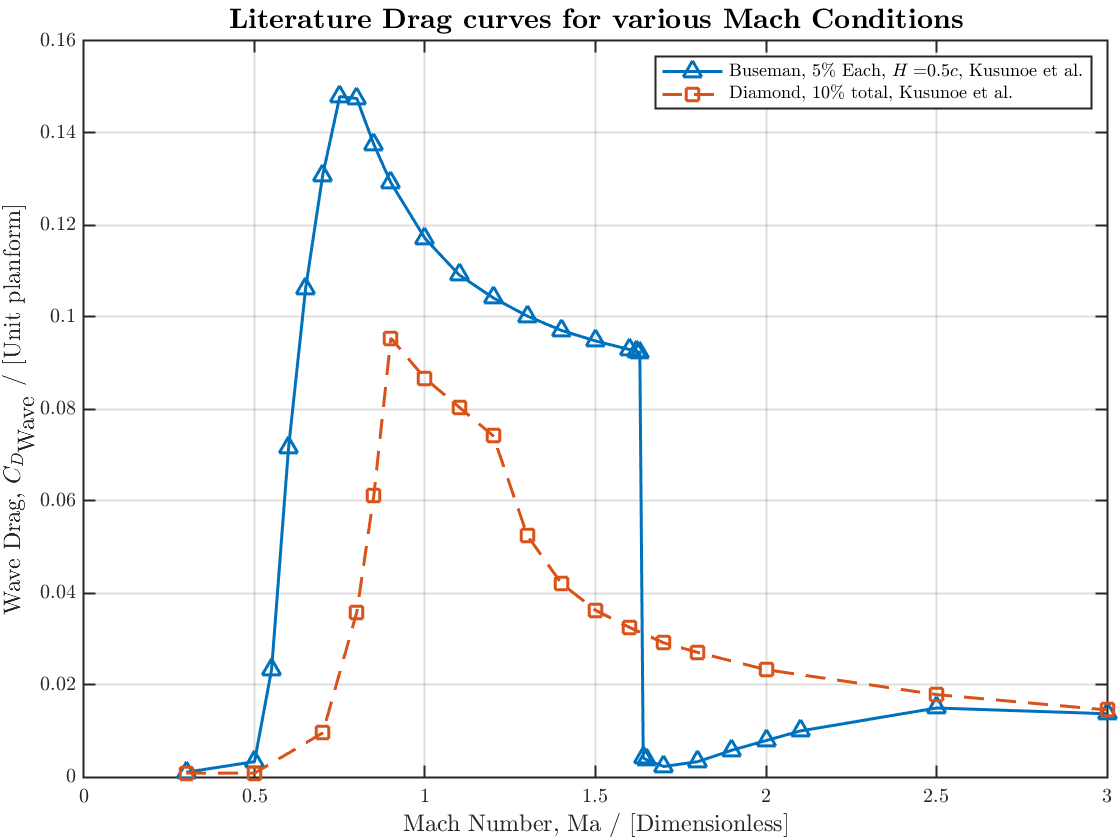

% Comparison to previuous data

% Kusunose et al. (2011)
MachRuns_buse = Kusunose_review_fig18_buseman_machs;
MachRuns_dia = Kusunose_review_fig18_diamond_machs;
Jpn_Busemann = Kusunose_review_fig18_buseman_cd;
Jpn_Diamond = Kusunose_review_fig18_diamond_cd;

%Jpn_alphas = [0:0.5:3.5];
%Jpn_dia_cl_euler =[0,0.0257,0.0515,0.0773,0.1031,0.1290,0.1550,0.1810];
%Jpn_dia_cdw_euler =[0.02891, 0.02914, 0.02983, 0.0316, 0.03264, 0.03475, 0.03734, 0.04041];
%Jpn_dia_LoverD_euler =Jpn_dia_cl_euler./Jpn_dia_cdw_euler;

figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",width,'markerSize',msize,'color',blue)
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",width,'markerSize',msize,'color',orange)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag curves for various Mach Conditions}",'FontSize',tsize)
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

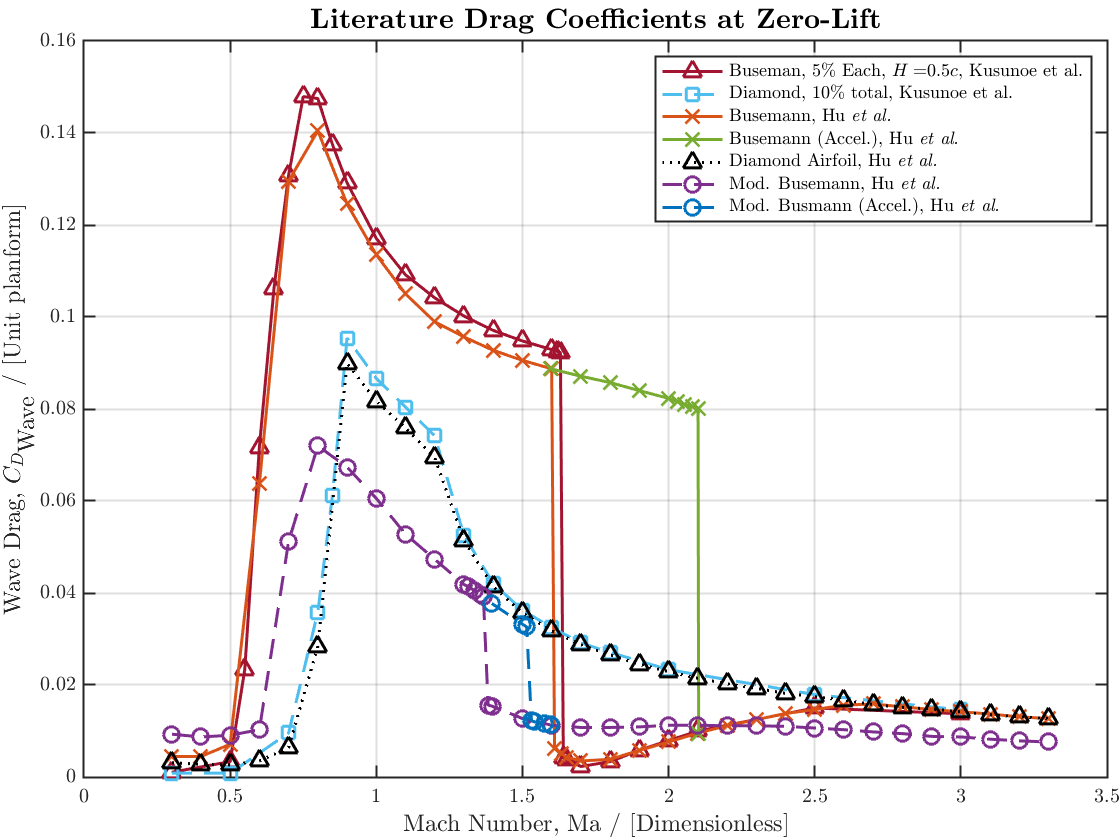


figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",width,'color',red,'markerSize',msize)
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",width,'color',lblue,'markerSize',msize)
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",width,'color',orange,'markerSize',msize)
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",width,'color',green,'markerSize',msize)
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",width,'color',black,'markerSize',msize)
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",width,'color',purple,'markerSize',msize)
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",width,'color',blue,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-Lift}",'FontSize',tsize)
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.","Busemann, Hu \textit{et al.}","Busemann (Accel.), Hu \textit{et al.}","Diamond Airfoil, Hu \textit{et al.}","Mod. Busemann, Hu \textit{et al.}","Mod. Busmann (Accel.), Hu \textit{et al.}", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Ma et al. (2020)

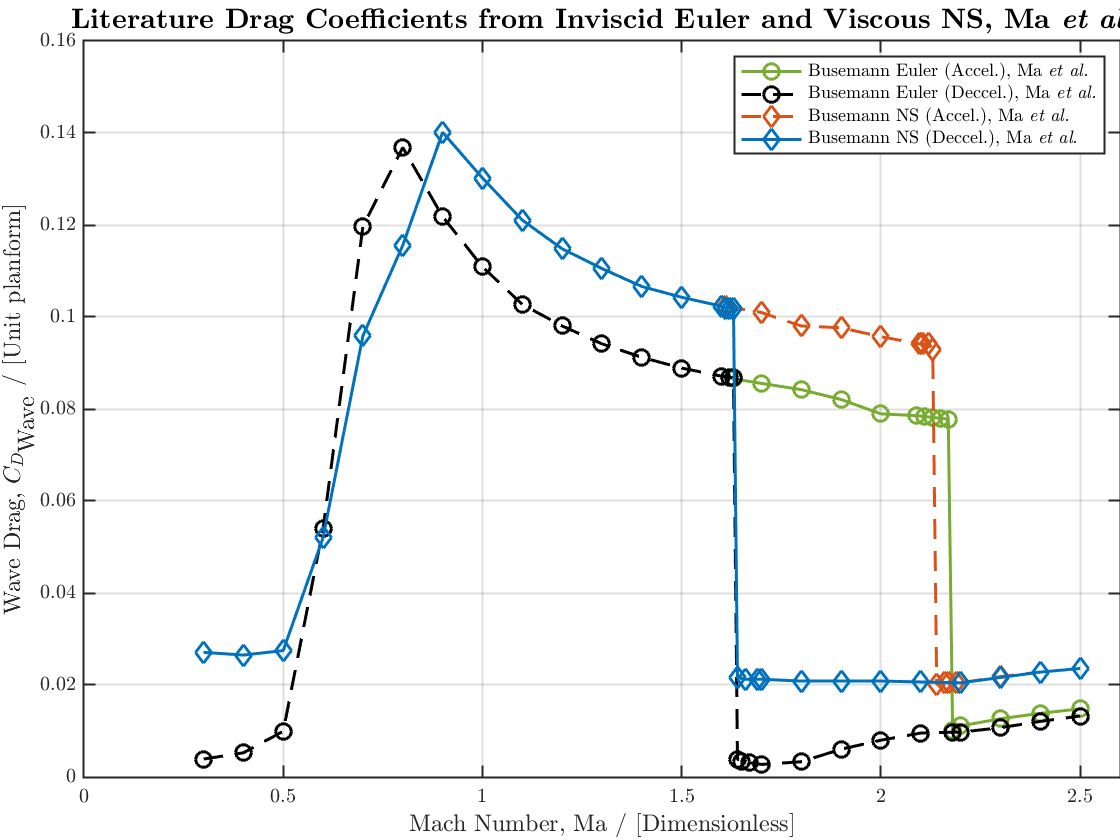

% Ma  - Avoiding choked flow and flow hystersis 
% of a buseman Biplane by Stagger

%FIG 12 - Drag coefficients with Navier stokes
% machs and drags
% Euller accel      Euler deccel    NS Accel    NS Deccel
Ma_fig_12_EulerAccelmachs   = [1.62,1.63,1.7,1.8,1.9,2,2.09,2.11,2.13,2.15,2.169,2.18,2.2,2.3,2.4,2.5];
Ma_fig_12_EulerAccel        = [0.08693957115009750,0.08654970760233920,0.08557504873294350,0.08421052631578950,0.08206627680311890,0.07894736842105260,0.07855750487329440,0.07836257309941520,0.07816764132553610,0.07797270955165690,0.07777777777777780,0.010136452241715300,0.011111111111111100,0.012670565302144300,0.01384015594541910,0.014814814814814800];
Ma_fig_12_EulerDeccelmachs  = [0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0,1.1,1.2,1.3,1.4,1.5,1.6,1.62,1.63,1.64,1.65,1.67,1.70,1.8,1.9,2.0,2.1,2.18,2.2,2.3,2.4,2.5];
Ma_fig_12_EulerDeccel       = [0.003898635477582850,0.0052631578947368600,0.009941520467836280,0.05399610136452240,0.11968810916179300,0.1368421052631580,0.12183235867446400,0.110916179337232,0.102729044834308,0.09805068226120860,0.09415204678362570,0.0912280701754386,0.08888888888888890,0.08713450292397660,0.08693957115009750,0.08674463937621830,0.0038986354775828700,0.0033138401559454400,0.003118908382066270,0.0027290448343080300,0.0033138401559454400,0.006042884990253410,0.007992202729044830,0.009551656920077980,0.009746588693957110,0.009746588693957110,0.010721247563352800,0.012085769980506800,0.013255360623781700];
Ma_fig_12_NSAccelmachs      = [1.61,1.7,1.8,1.9,2.0,2.097,2.105,2.12,2.13,2.14,2.16,2.17,2.19,2.2,2.3,2.4,2.5];
Ma_fig_12_NSAccel           = [0.10233918128655000,0.10097465886939600,0.09805068226120860,0.09766081871345030,0.09571150097465890,0.09415204678362570,0.09415204678362570,0.09415204678362570,0.09298245614035090,0.020077972709551700,0.020467836257310000,0.020467836257310000,0.020467836257310000,0.020467836257310000,0.021832358674464000,0.022807017543859700,0.02358674463937620];
Ma_fig_12_NSDeccelmachs     = [0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.62,1.63,1.64,1.66,1.69,1.70,1.80,1.90,2.00,2.10,2.20,2.30,2.40,2.50];
Ma_fig_12_NSDeccel          = [0.027095516569200800,0.026510721247563400,0.027485380116959100,0.05204678362573100,0.09590643274853800,0.11559454191033100,0.1401559454191030,0.13021442495126700,0.12105263157894700,0.11481481481481500,0.1105263157894740,0.10662768031189100,0.10428849902534100,0.10233918128655000,0.10194931773879100,0.10194931773879100,0.10194931773879100,0.02163742690058480,0.021247563352826500,0.021247563352826500,0.021247563352826500,0.02085769980506820,0.02085769980506820,0.02085769980506820,0.020662768031189100,0.020467836257310000,0.02163742690058480,0.022807017543859700,0.02358674463937620];

figure
plot(Ma_fig_12_EulerAccelmachs,Ma_fig_12_EulerAccel,'o-',"LineWidth",width,'color',green,'markerSize',msize)
hold on
plot(Ma_fig_12_EulerDeccelmachs,Ma_fig_12_EulerDeccel,'o--',"LineWidth",width,'color',black,'markerSize',msize)
plot(Ma_fig_12_NSAccelmachs,Ma_fig_12_NSAccel,'d--',"LineWidth",width,'color',orange,'markerSize',msize)
plot(Ma_fig_12_NSDeccelmachs,Ma_fig_12_NSDeccel,'d-',"LineWidth",width,'color',blue,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients from Inviscid Euler and Viscous NS, Ma \textit{et al.}}",'FontSize',tsize)
legend("Busemann Euler (Accel.), Ma \textit{et al.}","Busemann Euler (Deccel.), Ma \textit{et al.}","Busemann NS (Accel.), Ma \textit{et al.}","Busemann NS (Deccel.), Ma \textit{et al.}","Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0 2.6]);ylim([0 0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

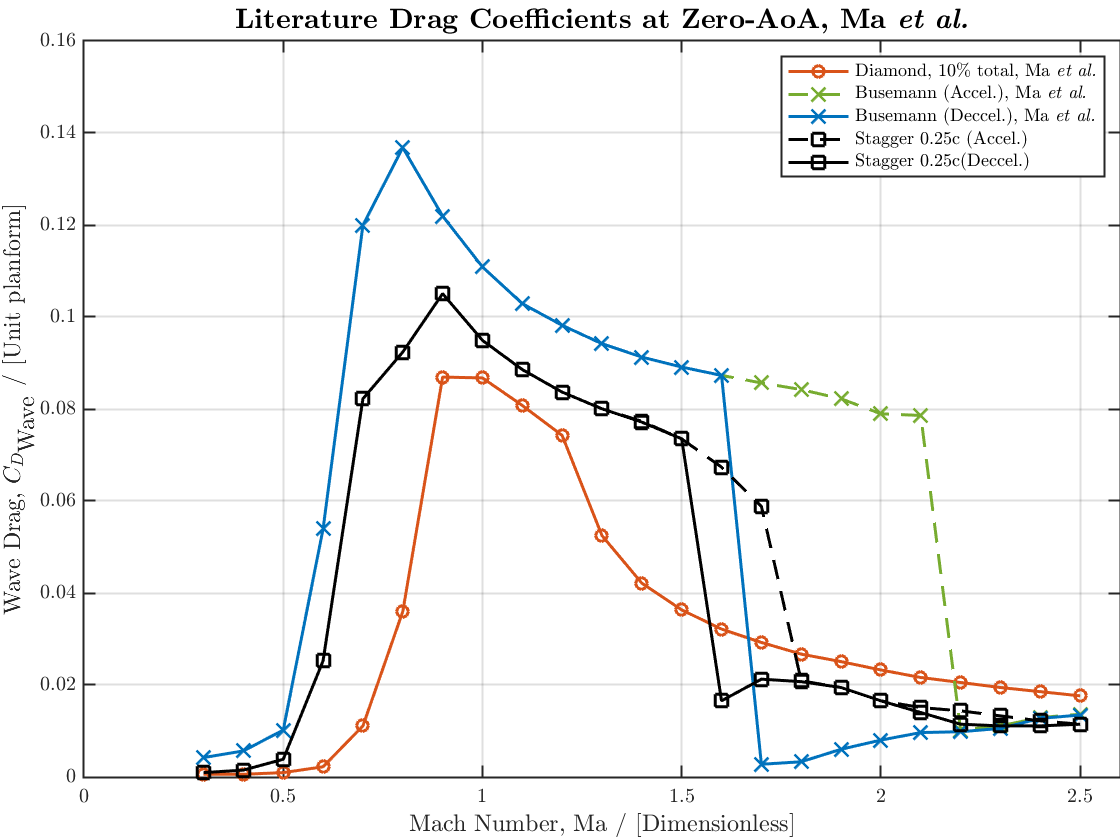


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 15 - drag coeff of acceleration process with Mach - inviscid
% Diamond, busemann accel., buseman deccel, right 0.25 accel, right 0.25 deccel
Ma_fig_15_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_15_Machs2 = [1.2:0.1:2.5]; %simple
Ma_fig_15_Diamond   =[0.0005895691609977270,0.0005895691609977270,0.0009523809523809550,0.0022222222222222100,0.0111111111111111,0.035963718820861600,0.08693877551020410,0.08675736961451250,0.08077097505668930,0.07424036281179140,0.052471655328798200,0.0421315192743764,0.03632653061224490,0.032154195011337800,0.02925170068027210,0.026712018140589500,0.025079365079365100,0.023265306122449000,0.02163265306122450,0.020544217687074800,0.019455782312925200,0.018548752834467100,0.01764172335600910];
Ma_fig_15_Buse_acc  =[0.09818594104308390,0.09419501133786850,0.0912925170068027,0.08911564625850340,0.08730158730158730,0.08566893424036280,0.08421768707482990,0.0822222222222222,0.07895691609977320,0.07859410430839,0.010204081632653100,0.0111111111111111,0.01292517006802720,0.013650793650793600];
Ma_fig_15_Buse_decc =[0.004217687074829920,0.0056689342403628,0.010204081632653100,0.05392290249433100,0.11995464852607700,0.1368253968253970,0.12195011337868500,0.11088435374149700,0.10290249433106600,0.09818594104308390,0.09419501133786850,0.0912925170068027,0.08911564625850340,0.08730158730158730,0.002766439909297040,0.003310657596371890,0.006031746031746030,0.008027210884353740,0.009659863945578220,0.009841269841269850,0.0105668934240363,0.012743764172335600,0.013469387755102000];
Ma_fig_15_025r_acc  =[0.08367346938775510,0.08004535147392290,0.07732426303854870,0.07351473922902490,0.06734693877551020,0.058820861678004500,0.020907029478458000,0.019455782312925200,0.0165532879818594,0.015102040816326500,0.014376417233560100,0.013287981859410400,0.012199546485260800,0.011473922902494300];
Ma_fig_15_025r_decc =[0.0009523809523809550,0.0014965986394557800,0.0038548752834466900,0.02526077097505670,0.0822222222222222,0.09238095238095240,0.10507936507936500,0.0949206349206349,0.08857142857142860,0.08367346938775510,0.08004535147392290,0.07714285714285710,0.07351473922902490,0.0165532879818594,0.021269841269841200,0.020725623582766400,0.019455782312925200,0.0165532879818594,0.014013605442176900,0.011473922902494300,0.0111111111111111,0.0111111111111111,0.011473922902494300];

figure
plot(Ma_fig_15_Machs,Ma_fig_15_Diamond,'o-',"LineWidth",width,'color',orange)
hold on
plot(Ma_fig_15_Machs2,Ma_fig_15_Buse_acc,'x--',"LineWidth",width,'color',green,'markerSize',msize)
plot(Ma_fig_15_Machs,Ma_fig_15_Buse_decc,'x-',"LineWidth",width,'color',blue,'markerSize',msize)
plot(Ma_fig_15_Machs2,Ma_fig_15_025r_acc,'s--',"LineWidth",width,'color',black,'markerSize',msize)
plot(Ma_fig_15_Machs,Ma_fig_15_025r_decc,'s-',"LineWidth",width,'color',black,'markerSize',msize)
%
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-AoA, Ma \textit{et al.}}",'FontSize',tsize)
legend("Diamond, 10\% total, Ma \textit{et al.}","Busemann (Accel.), Ma \textit{et al.}","Busemann (Deccel.), Ma \textit{et al.}","Stagger 0.25c (Accel.)","Stagger 0.25c(Deccel.)", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
xlim([0 2.6])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

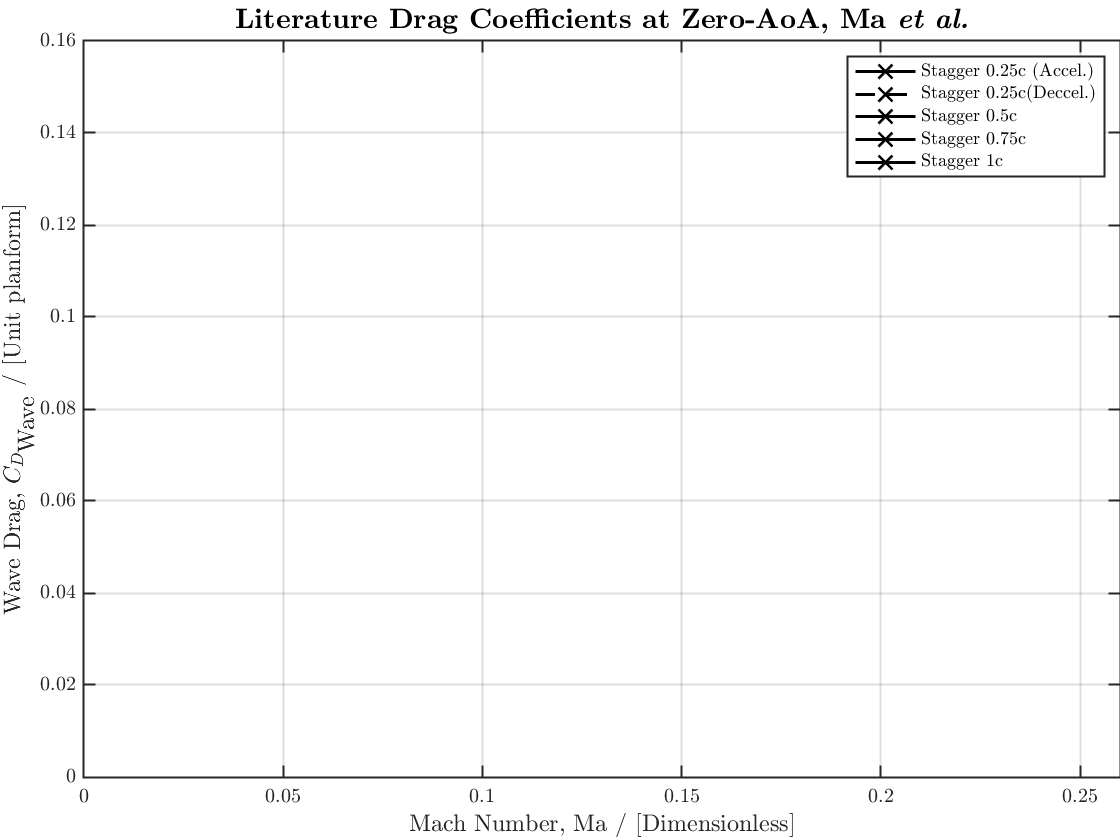


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 17 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, right 0.5 accel, right 0.5 deccel
Ma_fig_17_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_17_05r_both  =[0.0034482758620689700,0.003632183908045960,0.0038160919540229700,0.009517241379310320,0.02533333333333330,0.04096551724137930,0.06818390804597700,0.061379310344827600,0.057701149425287400,0.05475862068965520,0.04813793103448270,0.029747126436781600,0.03195402298850570,0.036367816091954,0.046850574712643600,0.04629885057471260,0.03986206896551720,0.03360919540229880,0.028643678160919500,0.02422988505747120,0.020551724137931000,0.017609195402298800,0.015218390804597700];

%FIG 19 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, right 0.75 accel, right 0.75 deccel
Ma_fig_19_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_19_075r_both  =[0.0035944700460829300,0.0035944700460829000,0.004331797235023000,0.007096774193548340,0.017788018433179700,0.04101382488479260,0.04894009216589860,0.05317972350230410,0.05059907834101380,0.05041474654377880,0.043778801843317900,0.04248847926267280,0.04414746543778800,0.0458064516129032,0.04635944700460830,0.04525345622119810,0.04341013824884790,0.04138248847926270,0.0393548387096774,0.03603686635944700,0.03271889400921650,0.029769585253456200,0.026820276497695800];

%FIG 21 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, right 1 accel, right 1 deccel
Ma_fig_21_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_21_1r_both  =[0.0031090487238978600,0.003665893271461660,0.003851508120649610,0.0051508120649652000,0.01554524361948950,0.04227378190255220,0.08348027842227380,0.07716937354988400,0.06714617169373550,0.043573085846867700,0.028352668213457000,0.024454756380510400,0.024454756380510400,0.025568445475638000,0.026867749419953600,0.02853828306264500,0.030023201856148500,0.031322505800464,0.031508120649651900,0.031322505800464,0.030951276102088100,0.030023201856148500,0.029466357308584700];

figure
plot(Ma_fig_15_Machs2,Ma_fig_15_025r_acc,'x-',"LineWidth",width,'color',black,'markerSize',msize)
hold on
plot(Ma_fig_15_Machs,Ma_fig_15_025r_decc,'x--',"LineWidth",width,'color',black,'markerSize',msize)
%
plot(Ma_fig_17_Machs,Ma_fig_17_05r_both,'x-',"LineWidth",width,'color',black,'markerSize',msize)
plot(Ma_fig_19_Machs,Ma_fig_19_075r_both,'x-',"LineWidth",width,'color',black,'markerSize',msize)
plot(Ma_fig_21_Machs,Ma_fig_21_1r_both,'x-',"LineWidth",width,'color',black,'markerSize',msize)
%
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-AoA, Ma \textit{et al.}}",'FontSize',tsize)
legend("Stagger 0.25c (Accel.)","Stagger 0.25c(Deccel.)","Stagger 0.5c","Stagger 0.75c","Stagger 1c", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
xlim([0 2.6])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

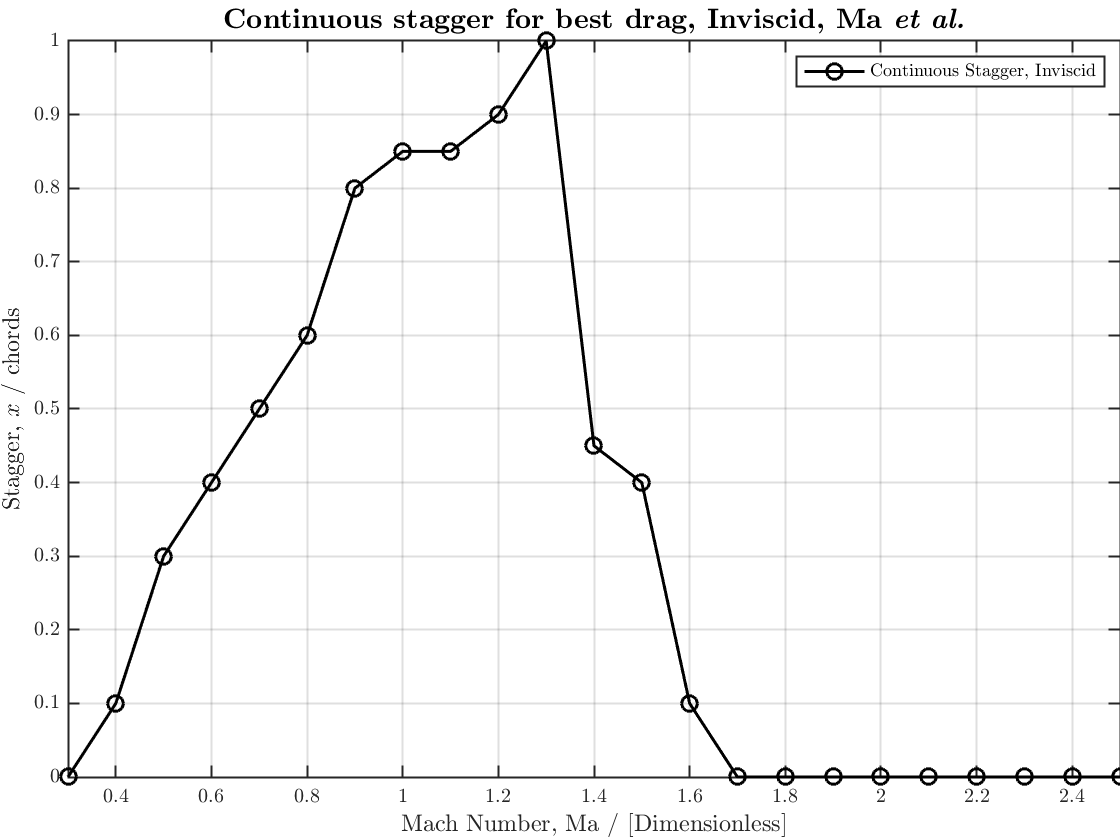


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 23 a and b - inviscid optimal continuous staggers (accel.) and then CD
% machs and stags
Ma_fig_23a_machs = [0.3:0.1:2.5];
Ma_fig_23a_stags = [0,0.1,0.3,0.4,0.5,0.6,0.8,0.85,0.85,0.90,1.00,0.45,0.40,0.10,0,0,0,0,0,0,0,0,0];
% machs and drags:  diamond, buse accel, buse decell, continuous
Ma_fig_23b_drag_continuous = [0.004481132075471710,0.002358490566037760,0.0014150943396226400,0.0028301886792452800,0.006839622641509450,0.017216981132075500,0.03797169811320760,0.039150943396226400,0.03702830188679250,0.033962264150943400,0.022877358490566000,0.02051886792452830,0.01627358490566040,0.0037735849056603800,0.0028301886792452800,0.003537735849056620,0.006132075471698110,0.008254716981132090,0.009669811320754730,0.01108490566037740,0.012264150943396200,0.013443396226415100,0.014858490566037700];

figure
plot(Ma_fig_23a_machs,Ma_fig_23a_stags,'o-',"LineWidth",width,'color',black,'markerSize',msize)
hold on
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Stagger, $x$ / chords",'FontSize',lsize)
title("\textbf{Continuous stagger for best drag, Inviscid, Ma \textit{et al.}}",'FontSize',tsize)
legend("Continuous Stagger, Inviscid", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);ylim([0 1]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

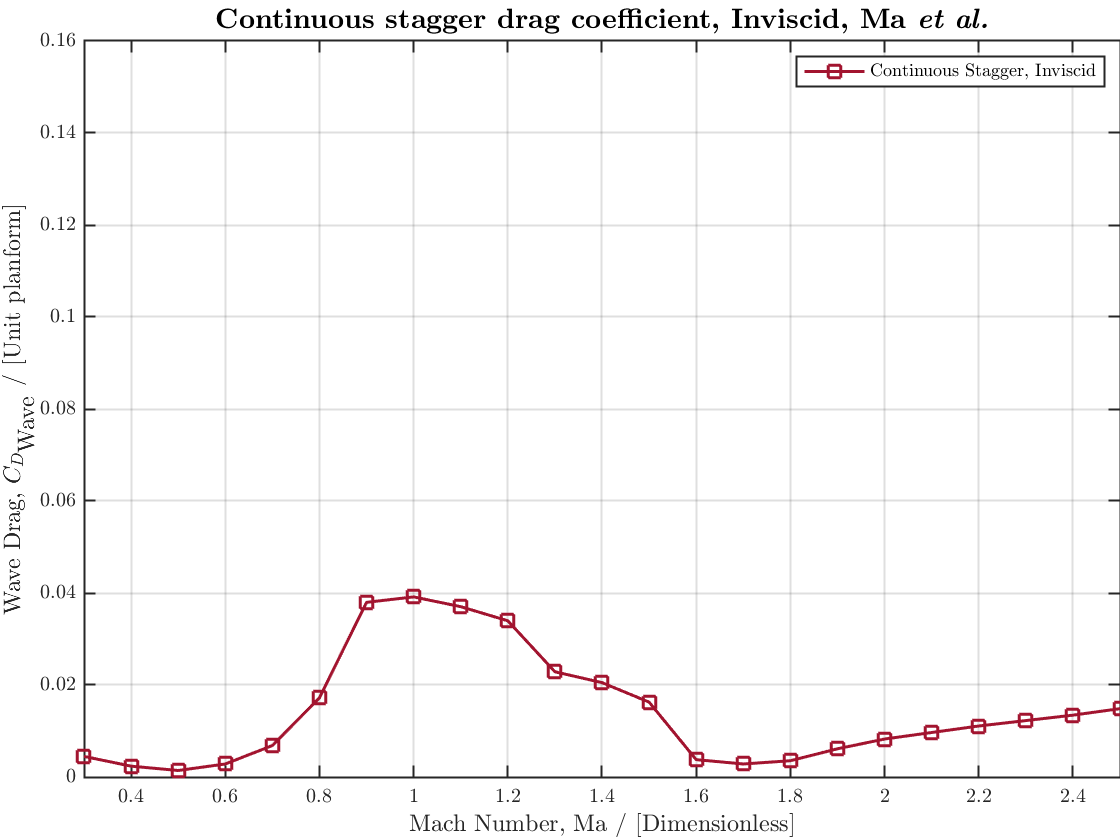


figure
plot(Ma_fig_23a_machs,Ma_fig_23b_drag_continuous,'s-',"LineWidth",width,'color',red,'markerSize',msize)
hold on
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Continuous stagger drag coefficient, Inviscid, Ma \textit{et al.}}",'FontSize',tsize)
legend("Continuous Stagger, Inviscid", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);ylim([0 0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


figure

xx=Ma_fig_23a_machs

xx =     0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


zz=Ma_fig_23a_stags

zz =          0    0.1000    0.3000    0.4000    0.5000    0.6000    0.8000    0.8500    0.8500    0.9000    1.0000    0.4500    0.4000    0.1000         0         0         0         0         0         0         0         0         0


dd=Ma_fig_23b_drag_continuous

dd =     0.0045    0.0024    0.0014    0.0028    0.0068    0.0172    0.0380    0.0392    0.0370    0.0340    0.0229    0.0205    0.0163    0.0038    0.0028    0.0035    0.0061    0.0083    0.0097    0.0111    0.0123    0.0134    0.0149


yy = 0.5*(ones(1,length(Ma_fig_23a_machs)))

yy =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000


cd = colormap('parula'); % take your pick (doc colormap)
cd = interp1(linspace(min(dd),max(dd),length(cd)),cd,dd) % map color to y values

cd =     0.2755    0.2367    0.8746
    0.2547    0.1747    0.7326
    0.2422    0.1504    0.6603
    0.2604    0.1876    0.7671
    0.2810    0.3240    0.9587
    0.0868    0.6857    0.8524
    0.9629    0.9381    0.1260
    0.9769    0.9839    0.0805
    0.9598    0.9002    0.1489
    0.9966    0.7736    0.2141


h=color_line3(xx,yy,zz,dd,'LineStyle','-','Marker','x',"LineWidth",width,'markerSize',msize) %// color binded to "y" values

h =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'none'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [23×2 double]
           YData: [23×2 double]
           ZData: [23×2 double]
           CData: [23×2 double]

  Show all properties


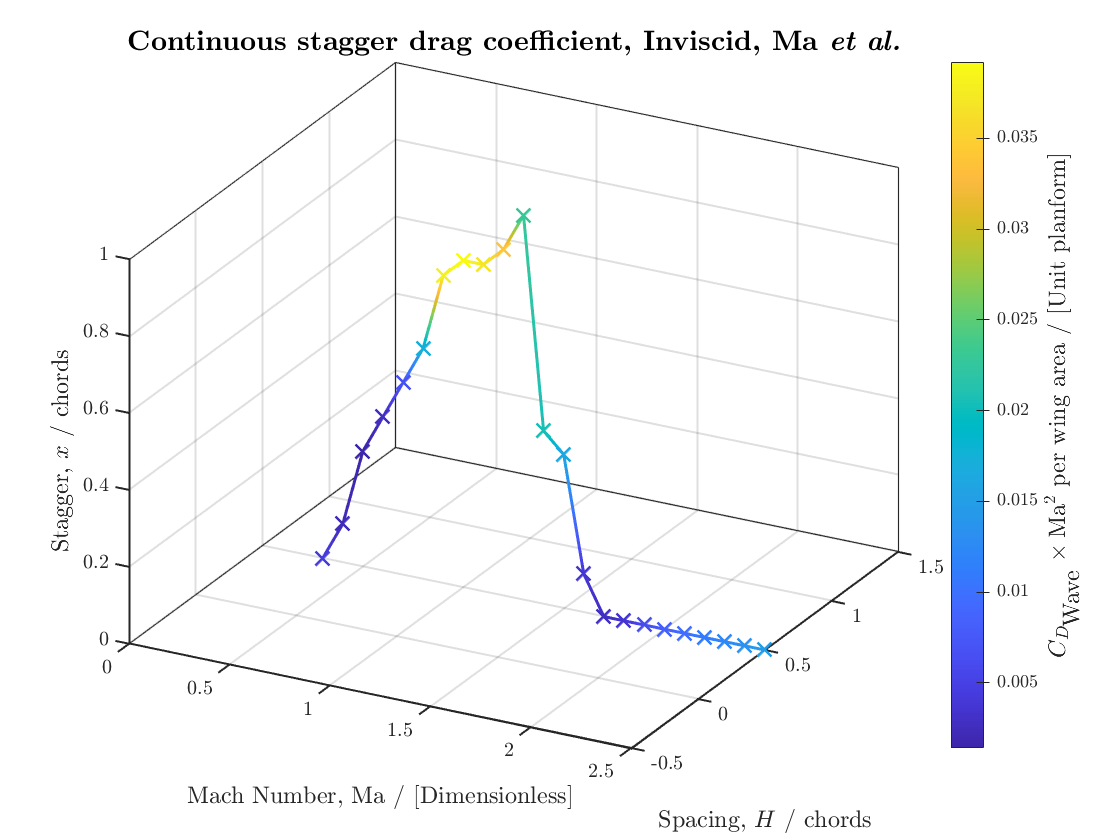

xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Spacing, $H$ / chords",'FontSize',lsize)
zlabel("Stagger, $x$ / chords",'FontSize',lsize)
%zlabel("Drag Coefficient, $C_{D}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Continuous stagger drag coefficient, Inviscid, Ma \textit{et al.}}",'FontSize',tsize)
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
ylabel(c,'$C_{D_{\textrm{Wave}}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
box on; grid on; hold off
H=gca; H.LineWidth=1;
view([28 30])


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

xx=Ma_fig_23a_machs

xx =     0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


yy=Ma_fig_23a_stags

yy =          0    0.1000    0.3000    0.4000    0.5000    0.6000    0.8000    0.8500    0.8500    0.9000    1.0000    0.4500    0.4000    0.1000         0         0         0         0         0         0         0         0         0


zz=Ma_fig_23b_drag_continuous

zz =     0.0045    0.0024    0.0014    0.0028    0.0068    0.0172    0.0380    0.0392    0.0370    0.0340    0.0229    0.0205    0.0163    0.0038    0.0028    0.0035    0.0061    0.0083    0.0097    0.0111    0.0123    0.0134    0.0149


dd=Ma_fig_23b_drag_continuous

dd =     0.0045    0.0024    0.0014    0.0028    0.0068    0.0172    0.0380    0.0392    0.0370    0.0340    0.0229    0.0205    0.0163    0.0038    0.0028    0.0035    0.0061    0.0083    0.0097    0.0111    0.0123    0.0134    0.0149


%yy = 0.5*(ones(1,length(Ma_fig_23a_machs)))

cd = colormap('parula'); % take your pick (doc colormap)
cd = interp1(linspace(min(dd),max(dd),length(cd)),cd,dd); % map color to y values

h=color_line3(xx,yy,zz,dd,'LineStyle','-','Marker','x',"LineWidth",width,'markerSize',msize) %// color binded to "y" values

h =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'none'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [23×2 double]
           YData: [23×2 double]
           ZData: [23×2 double]
           CData: [23×2 double]

  Show all properties


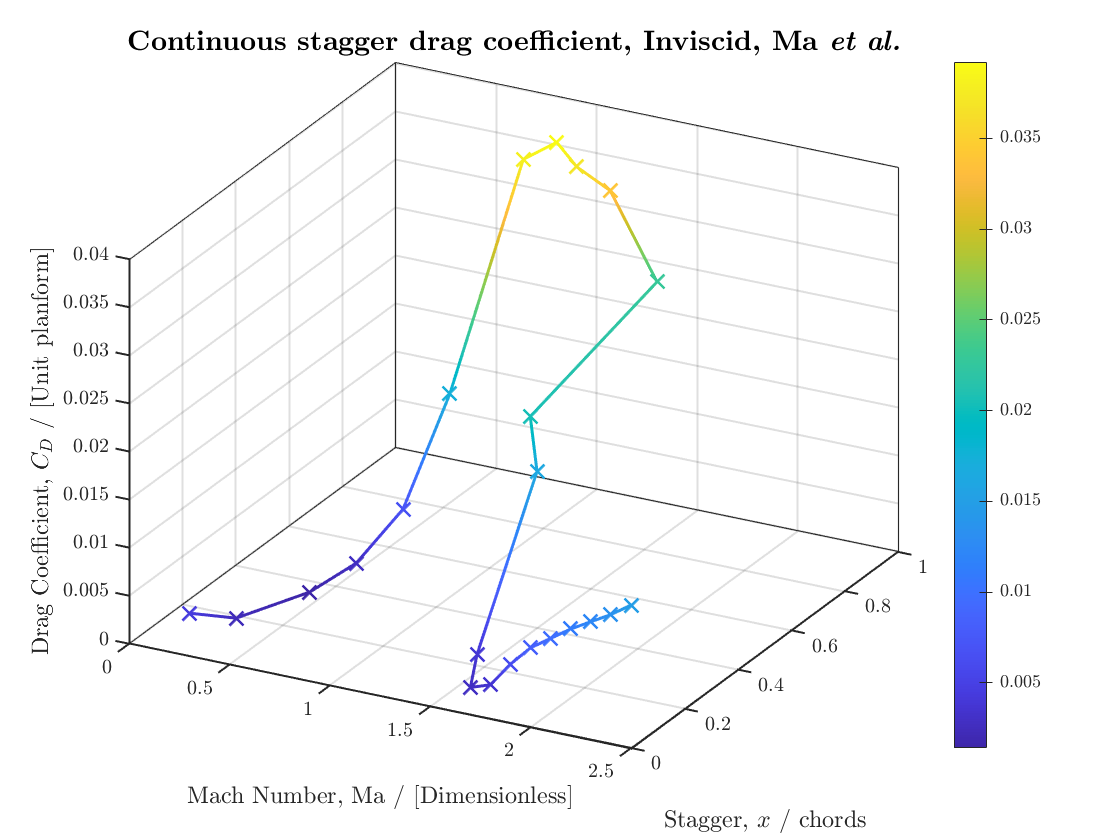


xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Stagger, $x$ / chords",'FontSize',lsize)
zlabel("Drag Coefficient, $C_{D}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Continuous stagger drag coefficient, Inviscid, Ma \textit{et al.}}",'FontSize',tsize)
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
box on; grid on; hold off
H=gca; H.LineWidth=1;
view([28 30])

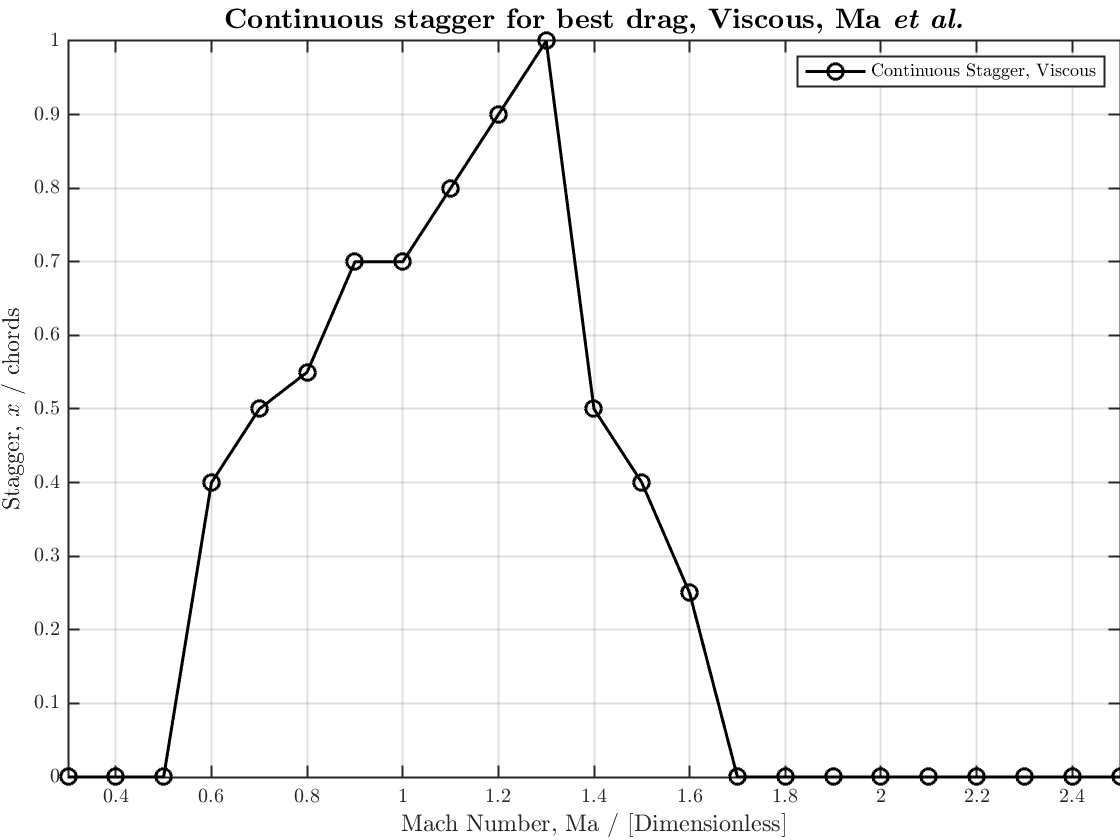


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 24 a and b - viscous optimal continuous staggers (accel.) and then CD
% machs and stags
Ma_fig_24a_machs = [0.3:0.1:2.5];
Ma_fig_24a_stags = [0,0,0,0.4,0.5,0.55,0.7,0.7,0.8,0.9,1,0.5,0.4,0.25,0,0,0,0,0,0,0,0,0];
% machs and drags - machs and viscous drags!
% diamond, buseman accel, busmean deccel, continuous - all at viscious
% drags
Ma_fig_24b_machs_diamond           =[0.3:0.1:2.5];
Ma_fig_24b_dragdiamond      =[0.012331838565022400,0.011883408071748800,0.011434977578475300,0.011434977578475300,0.016367713004484300,0.04058295964125560,0.1013452914798210,0.09260089686098650,0.08609865470852020,0.07982062780269060,0.060089686098654700,0.04887892376681610,0.0428251121076233,0.03856502242152470,0.03542600896860990,0.032735426008968600,0.030493273542600900,0.02869955156950670,0.027130044843049300,0.02578475336322870,0.024439461883408100,0.02354260089686100,0.022197309417040400];
Ma_fig_24b_buseaccelMachs   =[1.5,1.6,1.7,1.8,1.90,2.000,2.0975,2.1125,2.1325,2.1375,2.1525,2.1775,2.1925];
Ma_fig_24b_dragbuse_accel   =[0.10448430493273500,0.10246636771300400,0.10112107623318400,0.09843049327354260,0.09775784753363230,0.09573991031390130,0.09439461883408070,0.09394618834080720,0.09304932735426010,0.019506726457399100,0.019955156950672700,0.02017937219730940,0.020179372197309400];
Ma_fig_24b_machs_busedeccel =[0.2975,0.4,0.5,0.6,0.7,0.8,0.9,1.0,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.630,1.6375,1.650,1.67,1.69,1.7,1.8,1.9,2.0,2.1,2.2,2.3,2.4,2.5];
Ma_fig_24b_dragbuse_decell  =[0.027130044843049300,0.026233183856502200,0.027578475336322900,0.05224215246636770,0.09596412556053810,0.11591928251121100,0.1403587443946190,0.13049327354260100,0.12130044843049300,0.11479820627802700,0.11053811659192800,0.10695067264574000,0.1044843049327350,0.10246636771300400,0.10224215246636800,0.1020179372197310,0.02152466367713000,0.021300448430493300,0.021076233183856500,0.021076233183856500,0.02085201793721970,0.02085201793721970,0.020627802690582900,0.020852017937219700,0.020627802690582900,0.020179372197309400,0.021748878923766800,0.022645739910313900,0.02354260089686100];
Ma_fig_24b_Machs_stag_cont  =[0.3:0.1:2.5];
Ma_fig_24b_drag_stag_cont   =[0.02511210762331840,0.026681614349775800,0.02757847533632290,0.030493273542600900,0.038340807174887900,0.04551569506726460,0.05538116591928250,0.06412556053811660,0.06143497757847530,0.05627802690582960,0.0475336322869955,0.04417040358744390,0.038340807174887900,0.02869955156950670,0.021076233183856500,0.02085201793721970,0.02085201793721970,0.020627802690582900,0.020403587443946200,0.020627802690582900,0.021524663677130000,0.022645739910313900,0.023318385650224200];

figure
plot(Ma_fig_24a_machs,Ma_fig_24a_stags,'o-',"LineWidth",width,'color',black,'markerSize',msize)
hold on
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Stagger, $x$ / chords",'FontSize',lsize)
title("\textbf{Continuous stagger for best drag, Viscous, Ma \textit{et al.}}",'FontSize',tsize)
legend("Continuous Stagger, Viscous", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);ylim([0 1]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

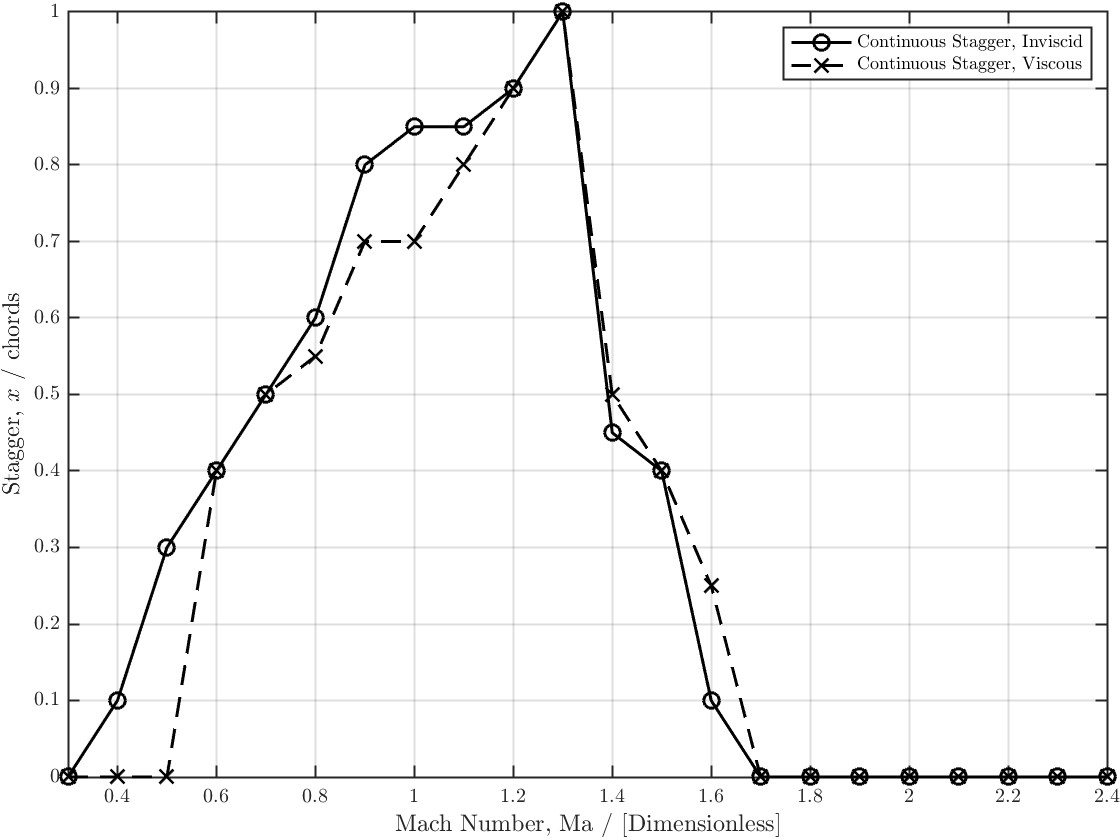


figure % INSERTED
plot(Ma_fig_23a_machs,Ma_fig_23a_stags,'o-',"LineWidth",width,'color',black,'MarkerSize',msize)
hold on
plot(Ma_fig_24a_machs,Ma_fig_24a_stags,'x--',"LineWidth",width,'color',black,'MarkerSize',msize)
hold on
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Stagger, $x$ / chords",'FontSize',lsize)
%title("\textbf{Continuous stagger for best drag, Viscous, Ma \textit{et al.}}",'FontSize',tsize)
legend("Continuous Stagger, Inviscid","Continuous Stagger, Viscous", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.4]);ylim([0 1]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

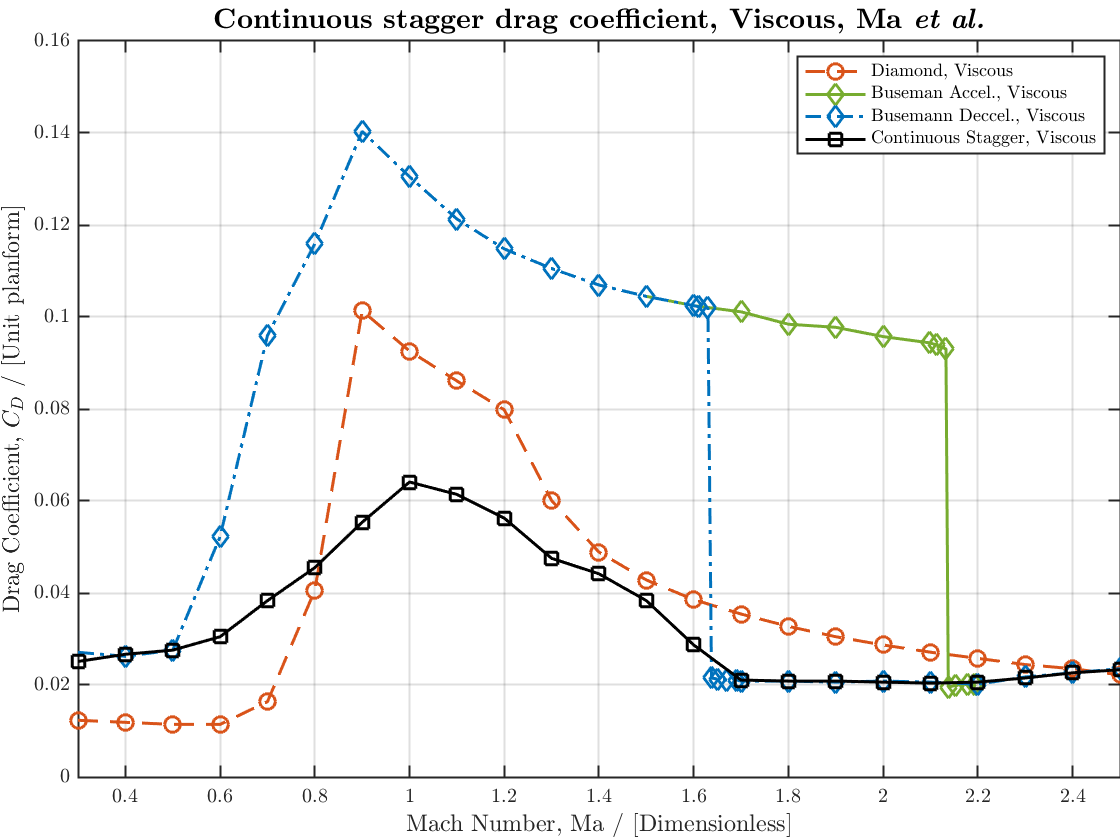


figure
plot(Ma_fig_24b_machs_diamond,Ma_fig_24b_dragdiamond,'o--',"LineWidth",width,'color',orange,'markerSize',msize)
hold on
plot(Ma_fig_24b_buseaccelMachs,Ma_fig_24b_dragbuse_accel,'d-',"LineWidth",width,'color',green,'markerSize',msize)
plot(Ma_fig_24b_machs_busedeccel,Ma_fig_24b_dragbuse_decell,'d-.',"LineWidth",width,'color',blue,'markerSize',msize)
plot(Ma_fig_24b_Machs_stag_cont,Ma_fig_24b_drag_stag_cont,'s-',"LineWidth",width,'color',black,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Drag Coefficient, $C_{D}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Continuous stagger drag coefficient, Viscous, Ma \textit{et al.}}",'FontSize',tsize)
legend("Diamond, Viscous","Buseman Accel., Viscous","Busemann Deccel., Viscous","Continuous Stagger, Viscous", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);ylim([0 0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

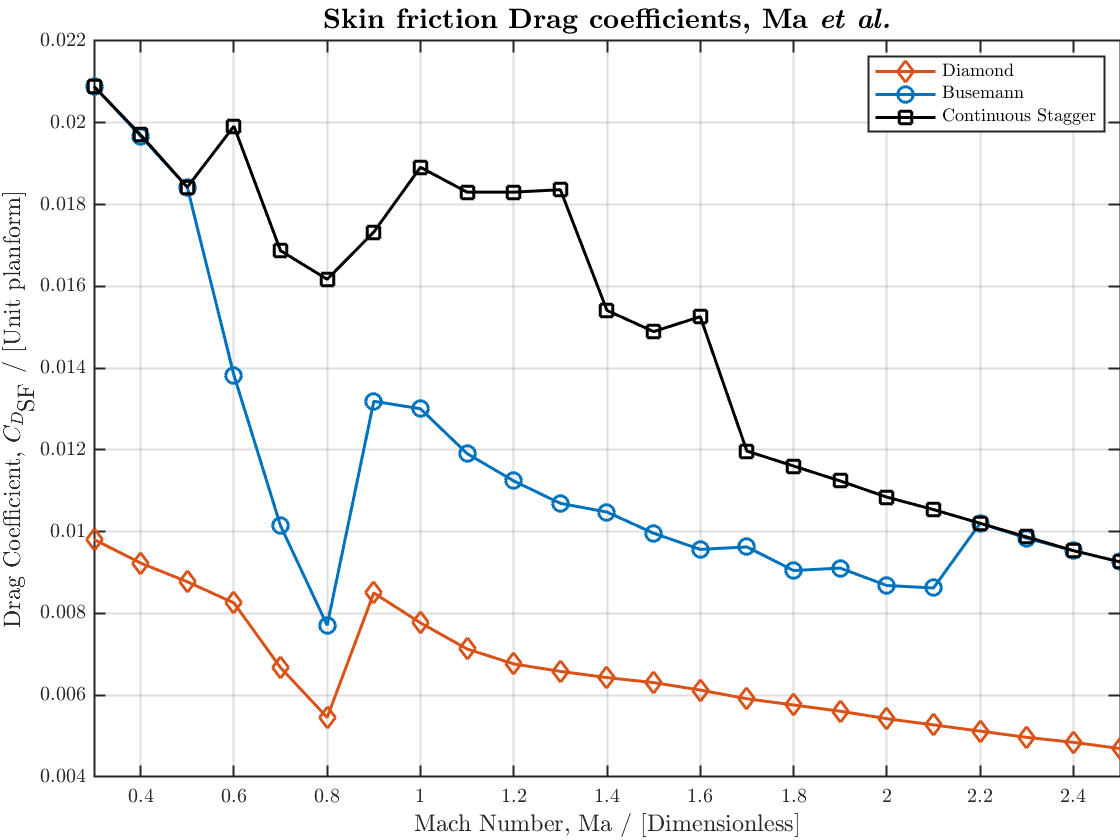


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 25 a and b - CDfriction and CDpressure for diamond, buseman and
%continuous
Ma_fig25_machs = [0.3:0.1:2.5];
% a. machs and drags
Ma_fig25_sfdrag_dia     =[0.009809741248097410,0.009231354642313550,0.008774733637747330,0.008257229832572300,0.00667427701674277,0.005456621004566210,0.00850076103500761,0.007770167427701670,0.007130898021308980,0.006765601217656010,0.0065829528158295300,0.00643074581430746,0.006308980213089800,0.006126331811263320,0.00591324200913242,0.005761035007610350,0.005608828006088280,0.005426179604261790,0.0052739726027397200,0.005121765601217650,0.004969558599695580,0.004847792998477930,0.00469558599695586];
Ma_fig25_sfdrag_buse    =[0.02089041095890410,0.01967275494672760,0.018424657534246600,0.01382800608828010,0.010144596651446000,0.007709284627092850,0.013188736681887400,0.013006088280060900,0.011910197869102000,0.01124048706240490,0.010692541856925400,0.01047945205479450,0.00996194824961948,0.009566210045662100,0.009627092846270930,0.009048706240487060,0.009109589041095890,0.008683409436834090,0.008622526636225270,0.010205479452054800,0.009840182648401830,0.009535768645357680,0.00926179604261796];
Ma_fig25_sfdrag_cont    =[0.02089041095890410,0.019703196347032000,0.018424657534246600,0.01991628614916290,0.01687214611872150,0.016171993911719900,0.01732876712328770,0.0189117199391172,0.01830289193302890,0.01830289193302890,0.018363774733637700,0.01541095890410960,0.014893455098934600,0.01525875190258750,0.011971080669710800,0.011605783866057800,0.01124048706240490,0.010844748858447500,0.010540334855403300,0.010205479452054800,0.009870624048706240,0.009535768645357680,0.00926179604261796];
% b. machs and drags
Ma_fig25_pressdrag_dia  =[0.0027290448343080000,0.002923976608187160,0.003118908382066300,0.003703703703703710,0.009746588693957140,0.03528265107212480,0.09278752436647180,0.08499025341130610,0.07914230019493180,0.07309941520467840,0.05341130604288500,0.042495126705653000,0.0368421052631579,0.03274853801169590,0.02962962962962960,0.027290448343079900,0.025341130604288500,0.02358674463937620,0.02202729044834310,0.02085769980506820,0.019688109161793400,0.018713450292397700,0.01773879142300200];
Ma_fig25_pressdrag_buse =[0.00623781676413257,0.00682261208576998,0.009356725146198840,0.0385964912280702,0.08596491228070180,0.1,0.11676413255360600,0.11734892787524400,0.10935672514619900,0.10350877192982500,0.1,0.09649122807017550,0.09454191033138400,0.09298245614035090,0.0916179337231969,0.08927875243664720,0.08869395711500980,0.08713450292397660,0.08576998050682260,0.010136452241715400,0.011890838206627700,0.01306042884990260,0.014230019493177400];
Ma_fig25_pressdrag_cont =[0.00623781676413257,0.00682261208576998,0.009356725146198840,0.010526315789473700,0.02163742690058480,0.029434697855750500,0.03801169590643280,0.045419103313840200,0.04307992202729050,0.03801169590643280,0.029239766081871400,0.02904483430799220,0.02358674463937620,0.013450292397660800,0.001949317738791420,0.002534113060428860,0.004483430799220280,0.00682261208576998,0.008771929824561400,0.01033138401559460,0.011890838206627700,0.013255360623781700,0.01423001949317740];

figure
plot(Ma_fig25_machs,Ma_fig25_sfdrag_dia,'d-',"LineWidth",width,'color',orange,'markerSize',msize)
hold on
plot(Ma_fig25_machs,Ma_fig25_sfdrag_buse,'o-',"LineWidth",width,'color',blue,'markerSize',msize)
plot(Ma_fig25_machs,Ma_fig25_sfdrag_cont,'s-',"LineWidth",width,'color',black,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Drag Coefficient, $C_{D_{\textrm{SF}}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Skin friction Drag coefficients, Ma \textit{et al.}}",'FontSize',tsize)
legend("Diamond","Busemann","Continuous Stagger", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

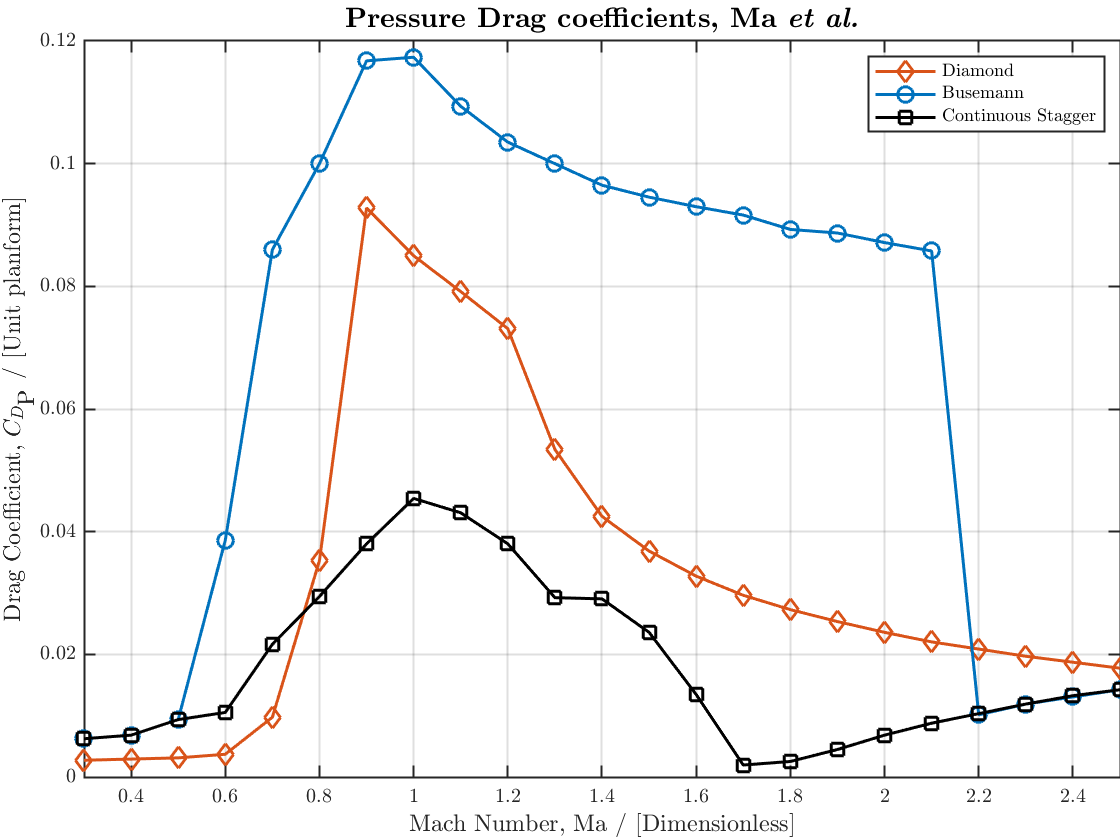


figure
plot(Ma_fig25_machs,Ma_fig25_pressdrag_dia,'d-',"LineWidth",width,'color',orange,'markerSize',msize)
hold on
plot(Ma_fig25_machs,Ma_fig25_pressdrag_buse,'o-',"LineWidth",width,'color',blue,'markerSize',msize)
plot(Ma_fig25_machs,Ma_fig25_pressdrag_cont,'s-',"LineWidth",width,'color',black,'markerSize',msize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Drag Coefficient, $C_{D_{\textrm{P}}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Pressure Drag coefficients, Ma \textit{et al.}}",'FontSize',tsize)
legend("Diamond","Busemann","Continuous Stagger", "Location","northeast","NumColumns",1,'FontSize',legsize)
xlim([0.3 2.5]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

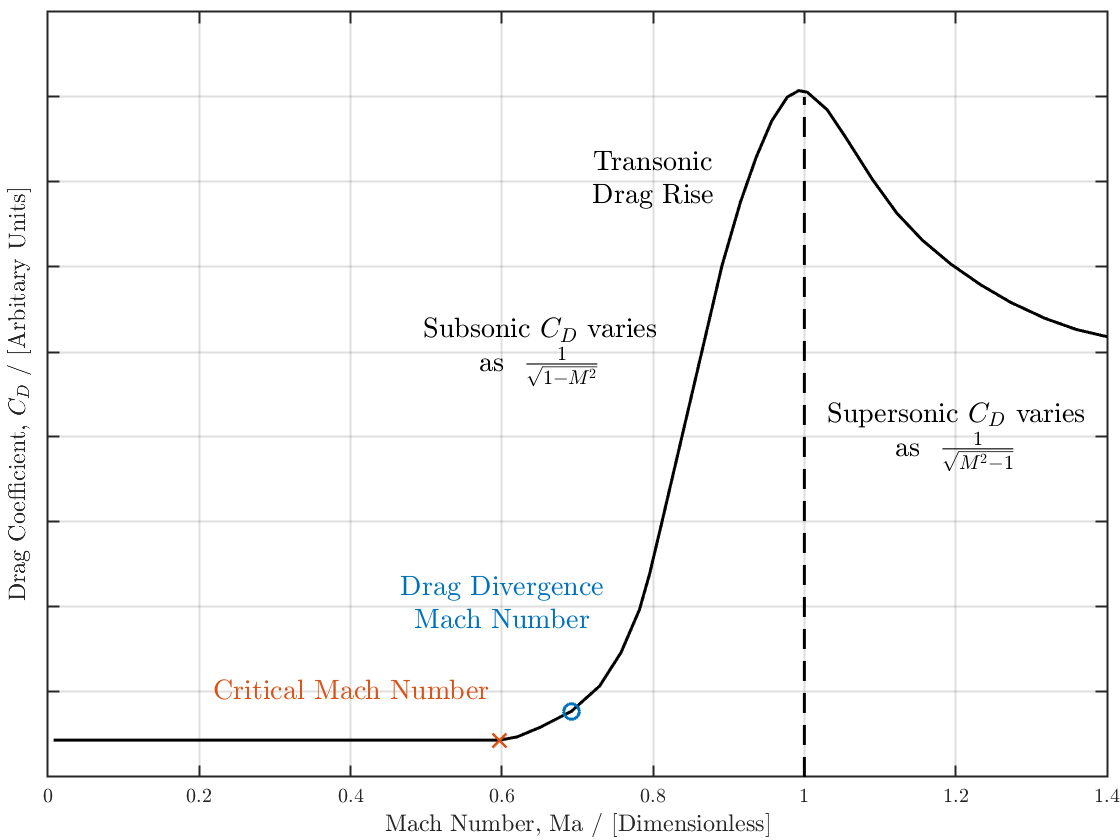

Machs_kirk = [0.007518796992481150,0.597443609022560,0.6203007518796990,0.650375939849624,0.6917293233082710,0.7293233082706770,0.7575187969924810,0.7819548872180450,0.7951127819548870,0.8101503759398500,0.8909774436090230,0.9154135338345870,0.9360902255639100,0.9567669172932330,0.9774436090225560,0.992481203007519,1.0037593984962400,1.0300751879699200,1.0526315789473700,1.0902255639097700,1.1221804511278200,1.1560150375939800,1.193609022556390,1.2330827067669200,1.2725563909774400,1.3176691729323300,1.3590225563909800,1.3947368421052600,1.4172932330827100];
cd_kirk = [0.2434456928838960,0.2434456928838960,0.24719101123595500,0.258426966292135,0.2771535580524350,0.30711610486891400,0.34644194756554300,0.39700374531835200,0.4382022471910110,0.4943820224719100,0.8014981273408240,0.8764044943820230,0.9288389513108620,0.9719101123595510,1.0000000000000000,1.00749063670412,1.0056179775280900,0.9850187265917610,0.955056179775281,0.9026217228464420,0.863295880149813,0.8314606741573040,0.8033707865168540,0.7790262172284650,0.758426966292135,0.7397003745318350,0.7265917602996260,0.7191011235955060,0.7153558052434460];

figure
hold on
plot(Machs_kirk,cd_kirk,'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)
grid on; box on; hold on
plot(0.597443609022560,0.2434456928838960,'x',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs_kirk(5),cd_kirk(5),'o',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot([1 1],[0 1],'--',"LineWidth",1.5,"MarkerSize",msize,"Color",black)
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Drag Coefficient, $C_{D}$ / [Arbitary Units]",'FontSize',lsize)
%legend('Top -1c (forward)','Top -0.75c (forward)','Top -0.5c (forward)','Top -0.25c (forward)','Top 0c (none)','Top 0.25c (aft)','Top 0.5c (aft)','Top 0.75c (aft)','Top 1c (aft)')
%title('\textbf{Accelerating stagger simulation Wave Drag Coefficients,} $-1c<x_{\textrm{top}}<1c$','FontSize',tsize)
hold on
xlim([0 1.4]); ylim([0.2 1.1])
set(gca,'yticklabel',{[' ']})
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

text1={'Critical Mach Number'};   textx1=0.4;  height1=0.3;
text2={'Drag Divergence', 'Mach Number'}; textx2=0.6; height2=0.4;
text3={'Transonic','Drag Rise'};       textx3=0.8;  height3=0.9;
t1 = text(textx1,height1,text1); t1.FontSize = tsize; t1.HorizontalAlignment = 'center'; t1.Color=orange;
t2 = text(textx2,height2,text2); t2.FontSize = tsize; t2.HorizontalAlignment = 'center'; t2.Color=blue;
t3 = text(textx3,height3,text3); t3.FontSize = tsize; t3.HorizontalAlignment = 'center'; t3.Color=black;

text4={'Subsonic $C_D$ varies','as $~\frac{1}{\sqrt{1-M^2}}$'};   textx4=0.65;  height4=0.7;
text5={'Supersonic $C_D$ varies','as $~\frac{1}{\sqrt{M^2-1}}$'}; textx5=1.2; height5=0.6;
t4 = text(textx4,height4,text4); t4.FontSize = tsize; t4.HorizontalAlignment = 'center'; t4.Color=black;
t5 = text(textx5,height5,text5); t5.FontSize = tsize; t5.HorizontalAlignment = 'center'; t5.Color=black;

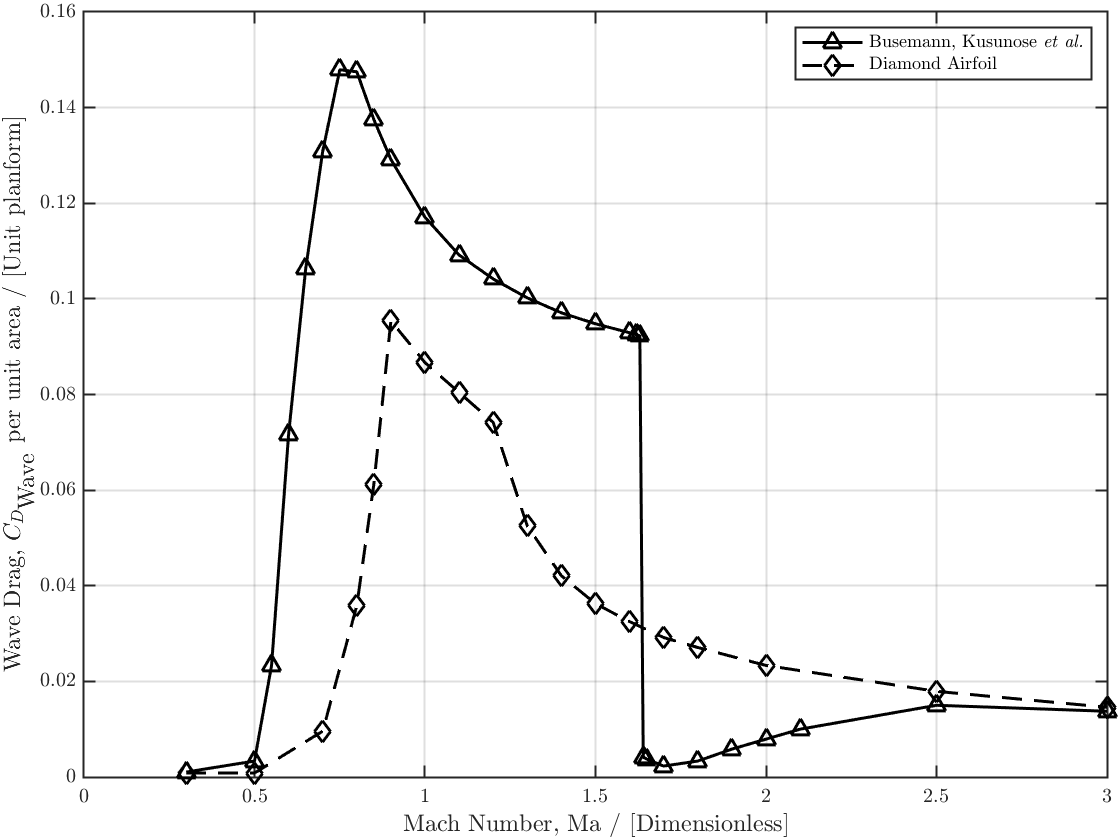

figure
plot(Kusunose_review_fig18_buseman_machs,Kusunose_review_fig18_buseman_cd,'^-',"LineWidth",width,'markerSize',msize,'color',black)
hold on
plot(Kusunose_review_fig18_diamond_machs,Kusunose_review_fig18_diamond_cd,'d--',"LineWidth",width,'markerSize',msize,'color',black)
hold on
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ per unit area / [Unit planform]",'FontSize',lsize)
%title("\textbf{Literature Drags for various configurations, Kusunose \textit{et al.} (2011)}",'FontSize',tsize)
legend("Busemann, Kusunose \textit{et al.}","Diamond Airfoil", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;
saveas(gcf,'Kusunose_drag.png')

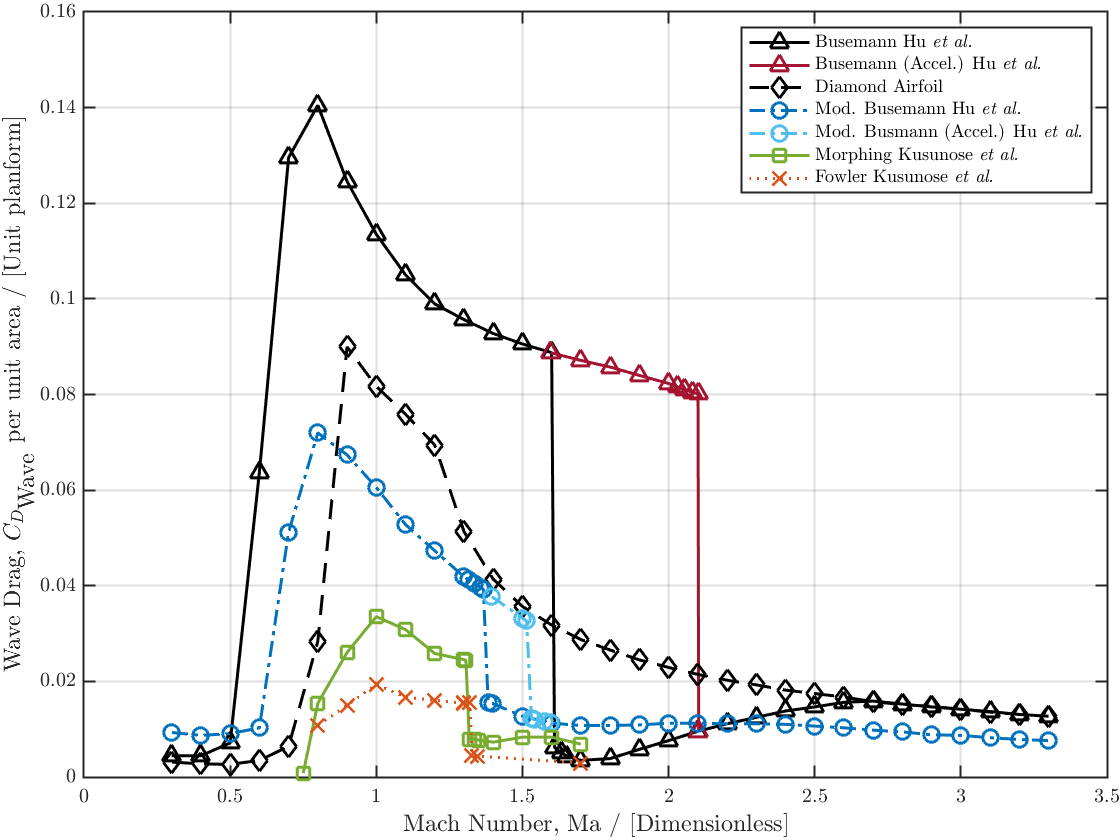


% OTHER FLOW CONTROL METHODS

figure
hold on
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'^-',"LineWidth",width,'color',black,'markerSize',msize)
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'^-',"LineWidth",width,'color',red,'markerSize',msize)
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'d--',"LineWidth",width,'color',black,'markerSize',msize)
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o-.',"LineWidth",width,'color',blue,'markerSize',msize)
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o-.',"LineWidth",width,'color',lblue,'markerSize',msize)

plot(Kusunose_review_fig18_morphing_machs,Kusunose_review_fig18_morphing_cd,'s-',"LineWidth",width,'color',green,'markerSize',msize)
plot(Kusunose_review_fig18_fowler_machs,Kusunose_review_fig18_fowler_cd,'x:',"LineWidth",width,'color',orange,'markerSize',msize)

xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ per unit area / [Unit planform]",'FontSize',lsize)
%title("\textbf{Literature Drag Coefficients at Zero-Lift, Hu \textit{et al.} (2011/12)}",'FontSize',tsize)
legend("Busemann Hu \textit{et al.}","Busemann (Accel.) Hu \textit{et al.}",...
    "Diamond Airfoil","Mod. Busemann Hu \textit{et al.}","Mod. Busmann (Accel.) Hu \textit{et al.}",...
    "Morphing Kusunose \textit{et al.}","Fowler Kusunose \textit{et al.}",...
    "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;
saveas(gcf,'Alternative_methods.png')

function h = color_line3(x, y, z, c, varargin)
% color_line3 plots a 3-D "line" with c-data as color
%
%       h = color_line(x, y, z, c)
%       by default: 'LineStyle','-' and 'Marker','none'
%
%          or
%       h = color_line(x, y, z, c, mark) 
%          or
%       h = color_line(x, y, z, c, 'Property','value'...) 
%             with valid 'Property','value' pairs for a surface object
%
%  in:  x      x-data
%       y      y-data
%       z      z-data
%       c      4th dimension for colouring
%       mark   for scatter plots with no connecting line
%
% out:  h   handle of the surface object
h = surface(...
  'XData',[x(:) x(:)],...
  'YData',[y(:) y(:)],...
  'ZData',[z(:) z(:)],...
  'CData',[c(:) c(:)],...
  'FaceColor','none',...
  'EdgeColor','interp',...
  'Marker','none');
  
if nargin ==5
    switch varargin{1}
        case {'+' 'o' '*' '.' 'x' 'square' 'diamond' 'v' '^' '>' '<' 'pentagram' 'p' 'hexagram' 'h'}
            set(h,'LineStyle','none','Marker',varargin{1})
        otherwise
            error(['Invalid marker: ' varargin{1}])
    end
elseif nargin > 5
    set(h,varargin{:})
end
end